As = 80;
Rp = 0.01;
Fs = 2048;

ws = 32*pi/1024;
wp = 30*pi/1024;
%M = ceil((As - 7.95)/(2.285*dwc))+1;
d1 = (1-db2mag(-Rp))/(1+db2mag(-Rp));
d2 = db2mag(-As)*(1+d1);
f = [30 32];
a = [1 0];
ds = [d1 d2];


[M, Wn, BTA, Filtype] = kaiserord(f,a,ds,Fs)

M = 5139

Wn = 0.0303

BTA = 7.8567

Filtype = 'low'

hd = ideal_lp((ws+wp)/2,M);
wk = kaiser(M,BTA)';
h = hd .* wk;
[db,mag,pha,grd,w] = freqz_m(h,[1]); delta_w = 2*pi/1000;
Rp = -(min(db(1:1:wp/delta_w+1))) % Actual Passband Ripple 

Rp = 3.9916e-04

As = -round(max(db(ws/delta_w+1:1:501))) % Min Stopband attenuation 

As = 92

figure;
subplot(2,1,1);
plot(w/pi,db);
length(w/pi)

ans = 501

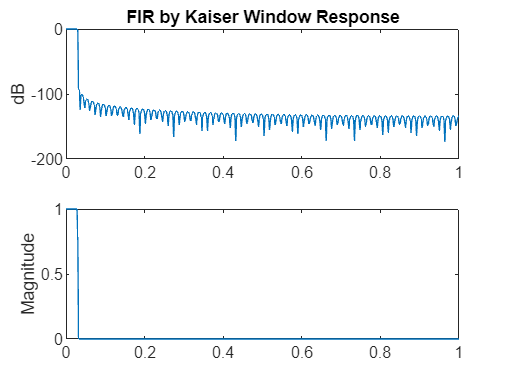

ylabel('dB');
title('FIR by Kaiser Window Response')
subplot(2,1,2);
plot(w/pi, mag);
ylabel('Magnitude')


[M, fo, ao, W]=firpmord(f,a,ds,Fs)

M = 4171

fo =          0
    0.0293
    0.0312
    1.0000


ao =      1
     1
     0
     0


W =     1.0000
    5.7532


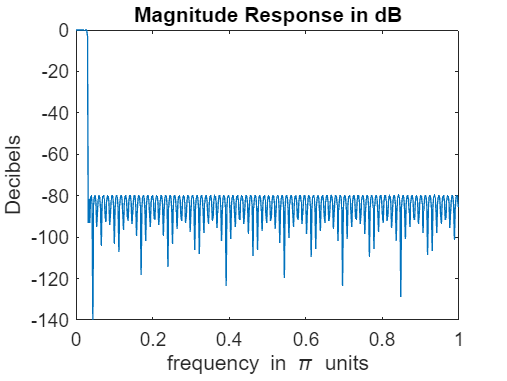

h = firpm(M,fo, ao, W);

[db,mag,pha,grd,w] = freqz_m(h,[1]); 
delta_w = 2*pi/1000;
% 3b
figure;
plot(w/pi,db);title('Magnitude Response in dB');
xlabel('frequency in \pi units');
ylabel('Decibels')

% 3c
As = -round(max(db(floor(ws/delta_w+2):1:501))) % Min Stopband Attenuation

As = 80

function hd = ideal_lp(wc, M); 
% Ideal LowPass filter computation 
% -------------------------------- 
% [hd] = ideal_lp(wc,M) 
% hd = ideal impulse response between 0 to M-1 
% wc = cutoff frequency in radians 
% M = length of the ideal filter
%
L = (M-1)/2; n = [0:1:(M-1)]; 
m = n - L; fc2 = wc/pi; hd = fc2*sinc(fc2*m); 
end
function [db,mag,pha,grd,w] = freqz_m(b,a); 
% Modified version of freqz subroutine 
% ------------------------------------ 
% [db,mag,pha,grd,w] = freqz_m(b,a); 
% db = Relative magnitude in dB computed over 0 to pi radians 
% mag = absolute magnitude computed over 0 to pi radians 
% pha = Phase response in radians over 0 to pi radians 
% grd = Group delay over 0 to pi radians 
% w = 501 frequency samples between 0 to pi radians 
% b = numerator polynomial of H(z) (for FIR: b=h) 
% a = denominator polynomial of H(z) (for FIR: a=[1]) 
%
[H,w] = freqz(b,a,1000,'whole'); 
H = (H(1:1:501))'; w = (w(1:1:501))';
mag = abs(H); 
db = 20*log10((mag)/max(mag)); 
pha = angle(H); 
grd = grpdelay(b,a,w); 
end